# Optimización Frenos (2022)

Se va a pasar a limpio el script ya existente: OptimizacionFrenos_bueno. m

## Parametros Vehiculo:

Datos del coche

%Masas y peso
M_coche=240;
M_piloto=70;
M=M_coche+M_piloto;
g=9.81;
P=M*g;

%Reparto de pesos
Delante=0.47;
Detras=0.53;
M_delante=M*Delante;
M_detras=M*Detras;
P_delante=P*Delante;
P_detras=P*Detras;

%Longitudes
L=1.55;
B=1.2;
l1=L*Detras;
l2=L*Delante;
h=0.3;

## Parametros sistema freno

Sacados de los spec sheets del fabricante.

%Pedalera
r_pedal=4;
Dbomba_d=0.0158;
Dbomba_t=0.0178;
Sbomba_d=(pi/4)*Dbomba_d.^2;
Sbomba_t=(pi/4)*Dbomba_t.^2;

%Pinzas
Npist_d=4;
Npist_t=2;
Dpist_d=0.025;
Dpist_t=0.025;
Spist_d=(pi/4)*Dpist_d.^2;
Spist_t=(pi/4)*Dpist_t.^2;
Coef_roz=0.35;

%Discos
Rext=0.094;
Rint=0.067;
Req=(2/3)*((Rext^3)-(Rint^3))/((Rext^2)-(Rint^2));

%Neumático
Ad=[1 1.2 1.5 2 2.2];
Ad_txt=string(Ad);
Ad_max=2;
Ad_max_txt=string(Ad_max);
Rneu=0.127;
Defneu=0.9;
Rcarga=Rneu*Defneu;

%Balance
Bal_d=[0.5 0.6 0.7 0.8];
Bal_t=1-Bal_d;
Bal_d_txt=string(Bal_d);
Bal_t_txt=string(Bal_t);

## Calculo teórico curva equiadherencia

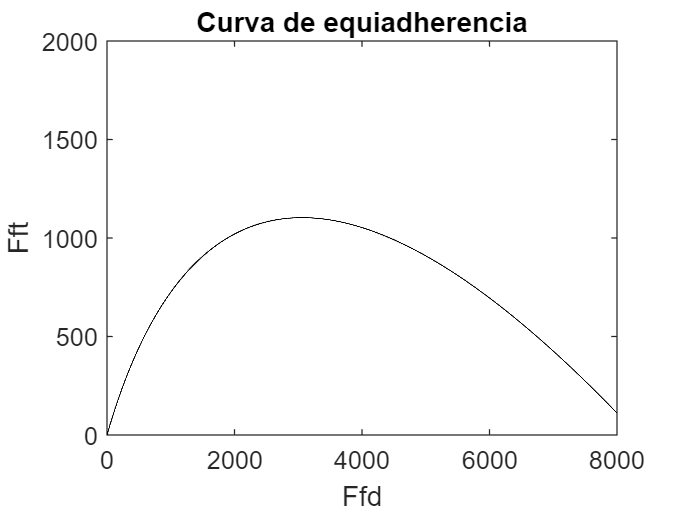

%% Curva de equiadherencia
Ffd=[0:1:8000];
a=1;
b=2*Ffd+(P/h)*l2;
c=(Ffd.^2)-(P/h)*Ffd*l1;
Fft=(-b+sqrt((b.^2)-4*a*c))/2*a;

for i=1:1:8000
coef_ad_equiad(i)=((Ffd(i)*l1)-(Fft(i)*l2))/((Ffd(i)+Fft(i)).*h);
end 

plot(Ffd,Fft,'k','DisplayName','Equiad');
xlim([0 8000]);
ylim([0 2000]);
title('Curva de equiadherencia');
xlabel('Ffd');
ylabel('Fft');
hold on;

## Calculo teorico lineas Isodeaceleracion

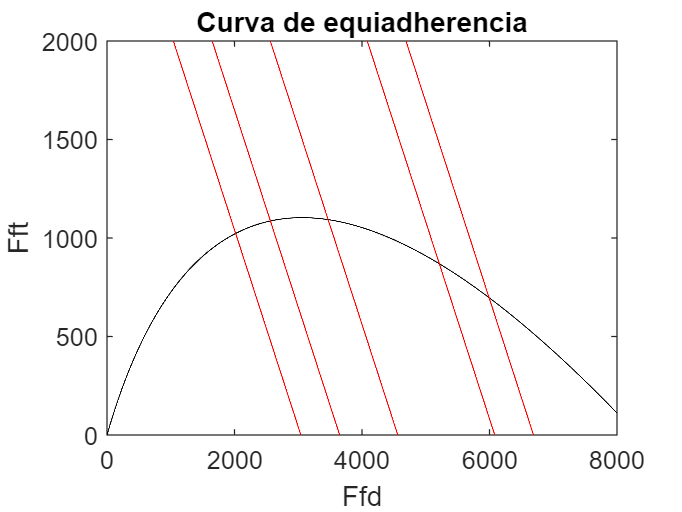

%% Isodaceleracion

size_Ad=length(Ad);
for i=1:1:size_Ad
   
namesIso_a(i)=["isoacel "];

end

for i=1:1:size_Ad
    
Isoacel=-Ffd+Ad(i).*P;
Name=strcat(namesIso_a,Ad_txt);

plot(Ffd,Isoacel,'r','DisplayName',Name(i));

end

## Calculo teorico lineas Isoadherencia delantera

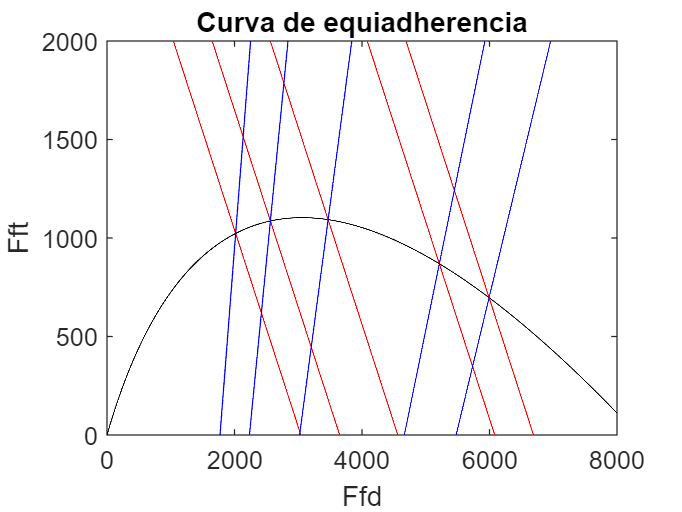

%% Isoadherencia delantera

for i=1:1:size_Ad
   
namesIso_d(i)=["isoAd_d "];

end

for i=1:1:size_Ad
    
Name=strcat(namesIso_d,Ad_txt);
Isoad_d=Ffd.*((L/(h*Ad(i)))-1)-(P*l2/h);
plot(Ffd,Isoad_d,'b','DisplayName',Name(i));

end

## Calculo teorico lineas Isoadherencia trasera

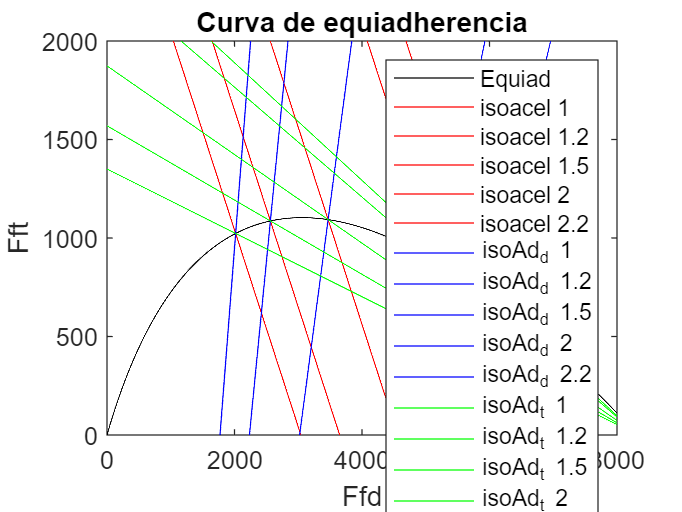

%% Isoadherencia trasera

for i=1:1:size_Ad
   
namesIso_t(i)=["isoAd_t "];

end

for i=1:1:size_Ad
    
Name=strcat(namesIso_t,Ad_txt);
Isoad_t=-Ffd.*((Ad(i)*h)/(L+Ad(i)*h))+(P*l1*Ad(i))/(L+(Ad(i)*h));
plot(Ffd,Isoad_t,'g','DisplayName',Name(i));

end

legend

## Balance Bar

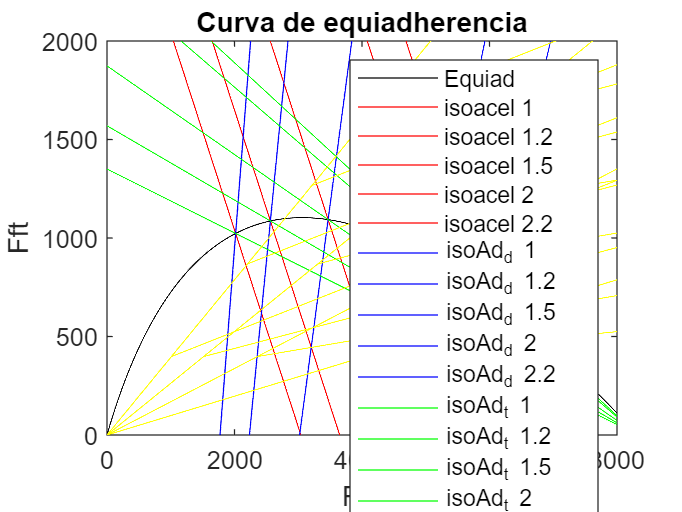

%% Balance bar
Name=strcat(Bal_d_txt," (d) / (t) ",Bal_t_txt);
Pht_N100=[38 44.5 50 55 60.5 66.5 73];
for z=1:1:length(Bal_d)
for i=1:1:length(Pht_N100)
for j=1:1:length(Ffd)
Phd(j)=(Ffd(j)*Rcarga)/(Spist_d*Npist_d*Coef_roz*Req*2);
Fpedal(z,j)=(Phd(j)*Sbomba_d)/(r_pedal*Bal_d(z));
Pht(i,j,z)=(Fpedal(z,j)*r_pedal*Bal_t(z))/(Sbomba_t);
y0=(Pht_N100(i)-(100*0.325))*10^5;
Pht1(i,j,z)=Pht(i,j,z)*0.325+y0;

            if Pht1(i,j,z)<Pht(i,j,z)
        Pht(i,j,z)=Pht1(i,j,z);
            end
        
Ffren(i,j,z)=Pht(i,j,z)*Spist_t*Npist_t*Coef_roz*(Req/Rcarga)*2;
coef_ad(i,j,z)=(Ffd(j)+Ffren(i,j,z))/P;
end
    if i==1
        legend('AutoUpdate','on')
        plot(Ffd(:),Ffren(i,:,z),'y','DisplayName',Name(z));
    else
    legend('AutoUpdate','off')
    plot(Ffd(:),Ffren(i,:,z),'y');
    end
    
end
end
hold off

## Optimización Frenada

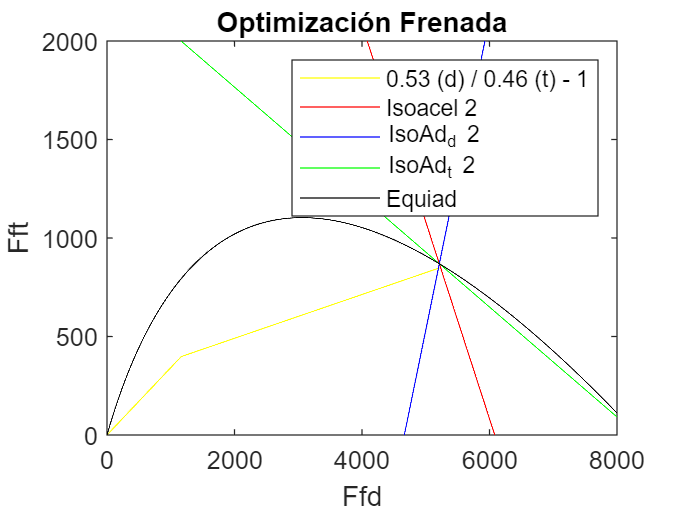

%% Optimización frenada
figure

Bal_opt_d=0.01:0.01:1;
Bal_opt_t=0.99-Bal_opt_d;


Fftotal=P*Ad_max;
%cálculo del tramo de la curva de equiadherencia que se quiere evaluar
Ffd_max=Ad_max*((P*l2/L)+(Fftotal*h/L));
Ffd_opt=0:1:Ffd_max;
a=1;
b=2*Ffd_opt+(P/h)*l2;
c=(Ffd_opt.^2)-(P/h)*Ffd_opt*l1;
Fft_opt=(-b+sqrt((b.^2)-4*a*c))/2*a;

Pht_N100=[38 44.5 50 55 60.5 66.5 73];
namesVal=["1" "2" "3" "4" "5" "6" "7"];

error=999999;
for z=1:1:length(Pht_N100)
for i=1:1:length(Bal_opt_d)

Phd_opt=(Ffd_opt.*Rcarga)/(Spist_d*Npist_d*Coef_roz*Req*2);
Fpedal_opt=(Phd_opt.*Sbomba_d)/(r_pedal*Bal_opt_d(i));
Pht_opt=(Fpedal_opt*r_pedal*Bal_opt_t(i))/(Sbomba_t);
y0=(Pht_N100(z)-(100*0.325))*10^5;
Pht1_opt=Pht_opt*0.325+y0;

        for j=1:1:length(Pht_opt)
            if Pht1_opt(j)<Pht_opt(j)
               Pht_opt(j)=Pht1_opt(j);
            end
        end
        
Ffren_opt=Pht_opt*Spist_t*Npist_t*Coef_roz*(Req/Rcarga)*2;
error0=norm(Fft_opt-Ffren_opt);
for k=1:1:length(Ffren_opt)
    if Ffren_opt(k)<Fft_opt(k)
        Condicion=1;
    else
        Condicion=0;
    end
end
if error0<error && Condicion==1
    
   Ffinal=Ffren_opt;
   error=error0;
   Bal_txt_d=string(Bal_opt_d(i));
   Bal_txt_t=string(Bal_opt_t(i));
   name=strcat(Bal_txt_d," (d) / ",Bal_txt_t," (t) - ",namesVal(z));
   
end
end
end
coef_ad_opt=(Ffd_opt+Ffinal)/P;
plot(Ffd_opt,Ffinal,'y','DisplayName',name);
hold on
legend 

Isoacel=-Ffd+Ad_max.*P;
Isoad_d=Ffd.*((L/(h*Ad_max))-1)-(P*l2/h);
Isoad_t=-Ffd.*((Ad_max*h)/(L+Ad_max*h))+(P*l1*Ad_max)/(L+(Ad_max*h));

plot(Ffd,Isoacel,'r','DisplayName',strcat("Isoacel ",Ad_max_txt));
plot(Ffd,Isoad_d,'b','DisplayName',strcat("IsoAd_d ",Ad_max_txt));
plot(Ffd,Isoad_t,'g','DisplayName',strcat("IsoAd_t ",Ad_max_txt));
plot(Ffd,Fft,'k','DisplayName','Equiad');

xlim([0 8000]);
ylim([0 2000]);
title('Optimización Frenada');
xlabel('Ffd');
ylabel('Fft');